## **Definir las coordenadas de nuestros vertices para cada placa **

Para esto creamos una función llamada crear_prisma que genera las coordenadas de los vertices de un prisma rectangular en 3D 

function vertices = crear_prisma(xc,yc,zc,ancho,largo,v)
    vertices = [
        -v*ancho + xc, -v*largo+yc, -v+zc;
        -v*ancho + xc, v*largo+yc, -v+zc;
        v*ancho + xc, v*largo + yc, -v + zc;
        v*ancho + xc, -v*largo + yc, -v + zc;
        -v*ancho + xc, -v*largo+yc, v+zc;
        -v*ancho + xc, v*largo+yc, v+zc;
        v*ancho + xc, v*largo + yc, v + zc;
        v*ancho + xc, -v*largo + yc, v + zc
        ];
end

## Valores iniciales 

qroja y qazul definen posiciones distintas para cada prisma, y v controla el tamaño de ambos

qroja = 10;
qazul = -10;
v=0.5;

Desplazamiento global 

dx = -1;
dy =0;
dz =0;


Dimensiones de las placas

largo_roja=3;
largo_azul=3;
ancho = 0.2;
alto =1;

Posiciones de las placas en x 

x_roja = dx;
x_azul = dx+2;


## Definimos el espacio en donde vamos a gráficar en 3D

figure;
hold on;
axis equal;
view(30,30);
axis([-2 2 -2 2 -2 2]);
grid on;


## Definimos las caras de los prismas 

Cada cara esta definida en base a los vértices que lo componen y esto lo guardamos en una matriz.

caras = [1 2 3 4;
         2 6 7 3;
         4 3 7 8;
         1 5 8 4;
         1 2 6 5;
         5 6 7 8];


## Creamos dos prismas en el espacio 

verticesRojo = crear_prisma(x_roja, dy, dz, ancho, largo_roja, v);
verticesAzul= crear_prisma(x_azul, dy,dz, ancho, largo_azul, v);


## Dibujamos las placas 

patch('Faces', caras,'Vertices', verticesRojo, 'FaceColor', 'r', 'FaceAlpha', 0.5)
patch('Faces', caras,'Vertices', verticesAzul, 'FaceColor', 'b', 'FaceAlpha', 0.5)


## Calculo de Campo

Se crea una linea de puntos de carga en el plano x,y 

Yq = meshgrid(-1.5:0.1:1.5, -0.5:0.1:0.5); 

Xq_roja = (x_roja + ancho*v) * ones(size(Yq)); 
Xq_azul = (x_azul - ancho*v) * ones(size(Yq));

num_cargas = numel(Yq);
dq_roja = qroja;
dq_azul = qazul;


Se crea el campo en el eje Z 0 y se crea una malla en el plano x,y para calcular el campo

[X_obs, Y_obs] = meshgrid(-2:0.1:2, -2:0.1:2);
Z_obs = zeros(size(X_obs)); 
Ex = zeros(size(X_obs));    
Ey = zeros(size(X_obs));    

k = 9000000000000000; 


Se hace un ciclo por todas las cargas en todos los puntos del plano donde calculamos el campo eléctrico y sumamos la superposicion de los campos de todas las cargas. Usamos la fórmula E = k * q * R/r^3 y evitamos la division entre 0.

for i = 1:num_cargas
    rx = X_obs - Xq_roja(i);
    ry = Y_obs - Yq(i);
    rz = Z_obs;
    dist3 = (rx.^2 + ry.^2 + rz.^2).^(3/2);
    dist3(dist3 < 0.000005) = 0.000005; 
    
    Ex = Ex + k * dq_roja .* (rx ./ dist3);
    Ey = Ey + k * dq_roja .* (ry ./ dist3);

    rx = X_obs - Xq_azul(i);
    ry = Y_obs - Yq(i);
    rz = Z_obs;
    dist3 = (rx.^2 + ry.^2 + rz.^2).^(3/2);
    dist3(dist3 < 0.05) = 0.05; 
    
    Ex = Ex + k * dq_azul .* (rx ./ dist3);
    Ey = Ey + k * dq_azul .* (ry ./ dist3);
end


Finalmente calculamos el vector resultantes y lo hacemos unitario para indicar la direccion de una manera visual y lo graficamos.

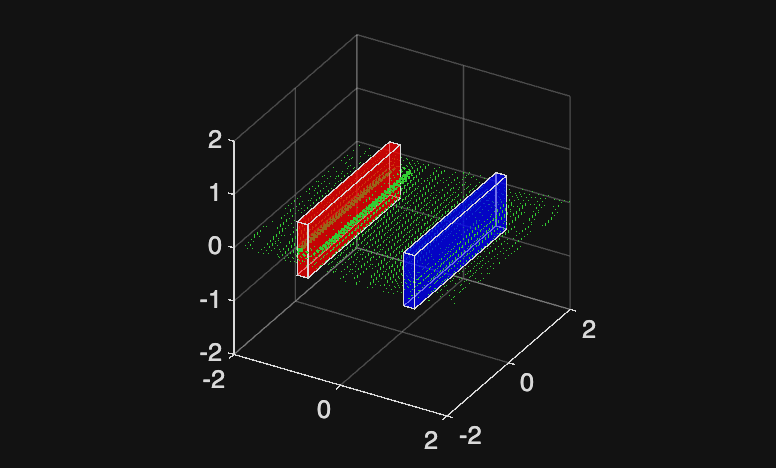

Magnitud_E = sqrt(Ex.^2 + Ey.^2);
Ex_norm = Ex ./ Magnitud_E;
Ey_norm = Ey ./ Magnitud_E;
Ez_norm = zeros(size(X_obs)); 

quiver3(X_obs, Y_obs, Z_obs, Ex_norm, Ey_norm, Ez_norm, 0.5, 'Color', [0.2 0.8 0.2], 'LineWidth', 1.2);